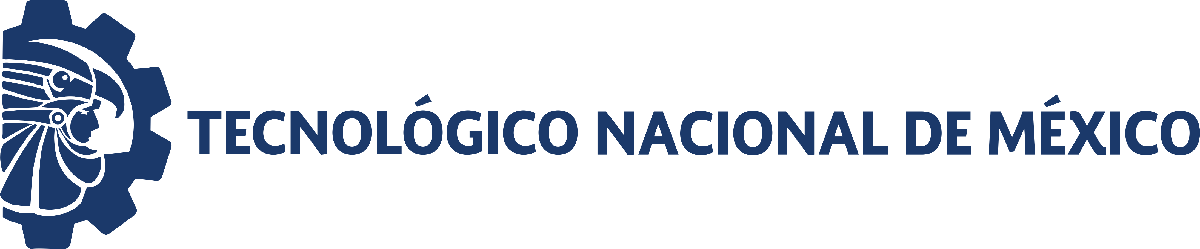                                 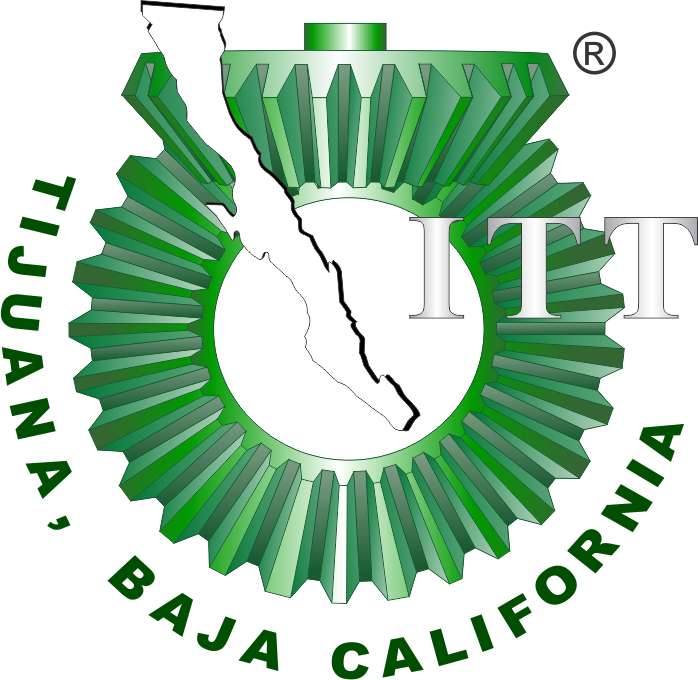

# Proyecto: Sistema respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

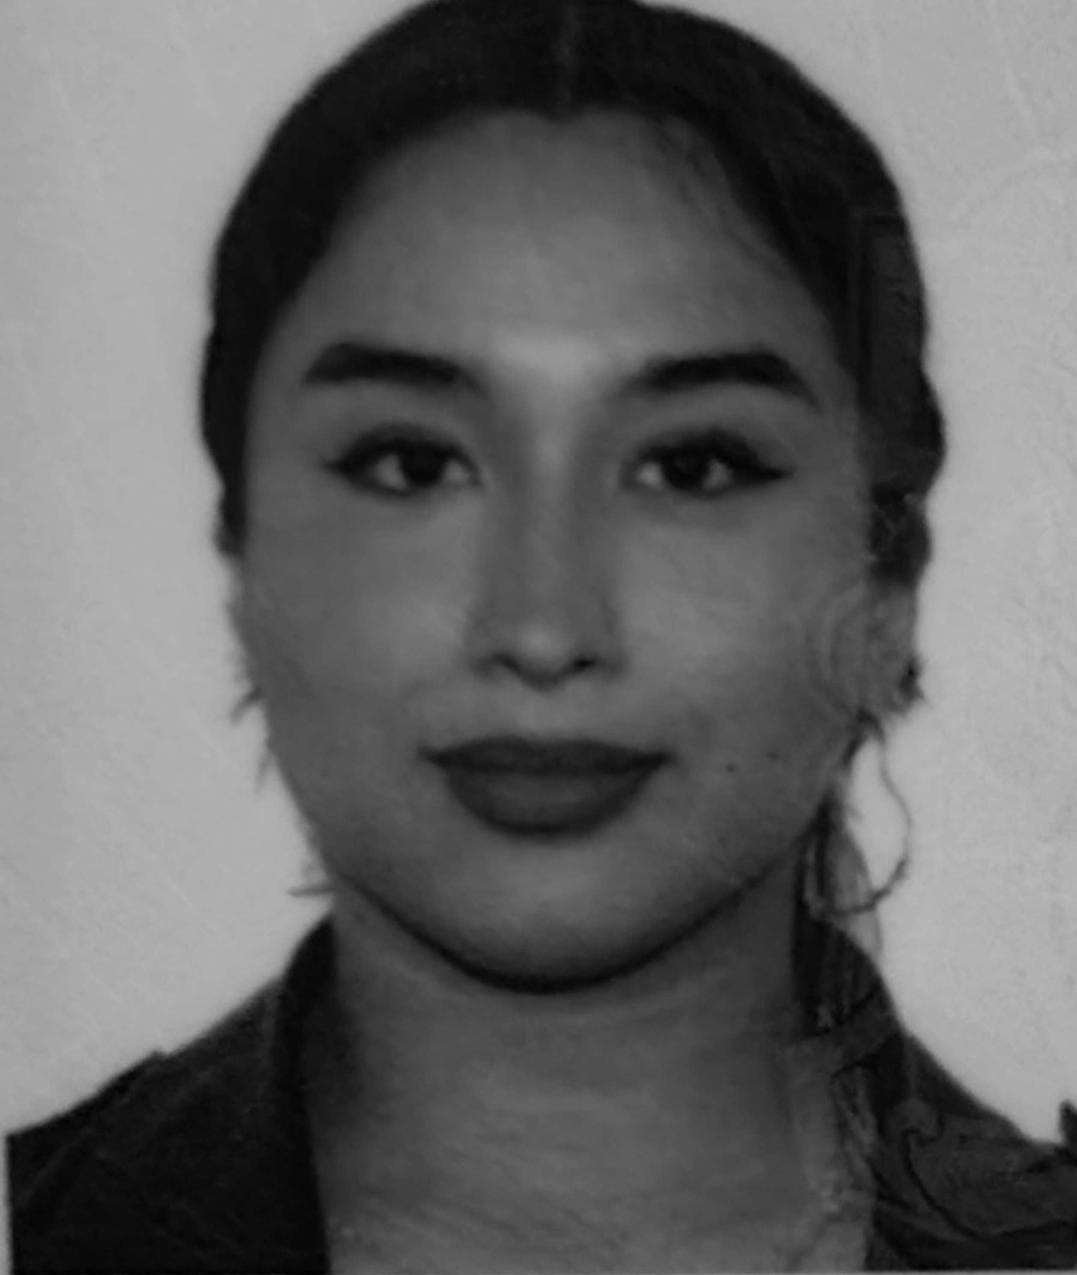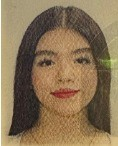

Nombre del alumno: **Osiris Jaylin Chavez Hernandez**

**                                  Angelica Ashia Haro Najar**

Número de control: **23210697**

**                                23210708**

Correo institucional: **l23210697@tectijuana.edu.mx**

**                                 l23210708@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

tend = '10';
file = 'Sistema';

open_system(file);

parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

x = sim(file, parameters);




## Respuesta del sistema

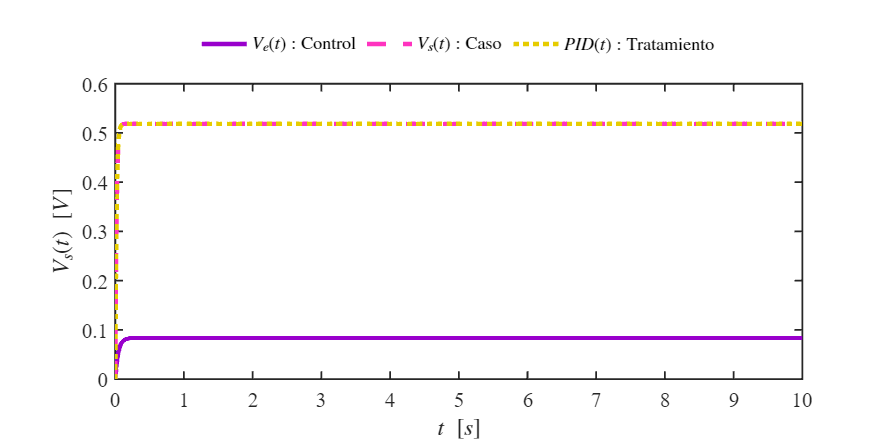

plotsignals(x.t, x.Pp1, x.Pp2, x.Pp3)

## Funcion: Respuesta a las señales    

function plotsignals(t, Pp1, Pp2, Pp3)

if isa(Pp1, 'timeseries')
    Pp1 = Pp1.Data;
end

if isa(Pp2, 'timeseries')
    Pp2 = Pp2.Data;
end

if isa(Pp3, 'timeseries')
    Pp3 = Pp3.Data;
end

t   = squeeze(t);   t   = t(:);
Pp1 = squeeze(Pp1); Pp1 = Pp1(:);
Pp2 = squeeze(Pp2); Pp2 = Pp2(:);
Pp3 = squeeze(Pp3); Pp3 = Pp3(:);

fig = figure();
set(fig, 'Color', 'w', 'Position', [100 100 1100 550])

box on; hold on;

plot(t, Pp1, '-',  'Color', [0.60 0.00 0.80], 'LineWidth', 3)
plot(t, Pp2, '--', 'Color', [1.00 0.20 0.75], 'LineWidth', 3)
plot(t, Pp3, ':',  'Color', [0.90 0.80 0.00], 'LineWidth', 3)

L = legend('$V_e(t): \mathrm{Control}$', ...
           '$V_s(t): \mathrm{Caso}$', ...
           '$PID(t): \mathrm{Tratamiento}$');

set(L, 'Interpreter',  'Latex', ...
       'FontSize',      12, ...
       'Location',      'northoutside', ...
       'Orientation',   'horizontal', ...
       'Box',           'Off');

xlabel('$t\ [s]$', 'Interpreter', 'Latex', 'FontSize', 15)
ylabel('$V_s(t)\ [V]$', 'Interpreter', 'Latex', 'FontSize', 15)

xlim([0, 10])
xticks(0:1:10)

ylim([0, 0.6])
yticks(0:0.1:0.6)

set(gca, 'FontName', 'Times New Roman', ...
         'FontSize', 14, ...
         'LineWidth', 1.2)

exportgraphics(gcf, 'respiratorio_control_caso_tratamiento.pdf', ...
               'ContentType', 'vector')

end